% I ran this section individually each time then ran the appropriate
% section below so that VphX wouldn't be overwritten
arduino = serial("/dev/cu.usbmodem142101",'BaudRate',9600);
pause(1)
fopen(arduino);
writedata=uint16(500); %0x01F4
VR = [0];

for i=1:101
    fwrite(arduino,writedata,'uint16')
    pause(.5)
    readData = fscanf(arduino,'%f')
    VR = [VR readData]; 
end

readData = 0

readData = 0.1800

readData = 0.3200

readData = 0.4400

readData = 0.5600

readData = 0.6500

readData = 0.7400

readData = 0.8500

readData = 0.9100

readData = 1

readData = 1.0500

readData = 1.1300

readData = 1.1800

readData = 1.2500

readData = 1.3300

readData = 1.3600

readData = 1.4200

readData = 1.4500

readData = 1.5200

readData = 1.5700

readData = 1.5900

readData = 1.6600

readData = 1.6600

readData = 1.7300

readData = 1.7700

readData = 1.7900

readData = 1.8500

readData = 1.8400

readData = 1.9100

readData = 1.9400

readData = 1.9600

readData = 2.0200

readData = 2.0100

readData = 2.0600

readData = 2.0800

readData = 2.1000

readData = 2.1500

readData = 2.1400

readData = 2.2000

readData = 2.2100

readData = 2.2300

readData = 2.2700

readData = 2.2700

readData = 2.3200

readData = 2.3200

readData = 2.3500

readData = 2.3800

readData = 2.3700

readData = 2.4300

readData = 2.4200

readData = 2.4500

readData = 2.4800

readData = 2.4800

readData = 2.5200

readData = 2.5100

readData = 2.5500

readData = 2.5600

readData = 2.5700

readData = 2.6000

readData = 2.5800

readData = 2.6400

readData = 2.6400

readData = 2.6500

readData = 2.6800

readData = 2.6700

readData = 2.7100

readData = 2.7100

readData = 2.7300

readData = 2.7500

readData = 2.7400

readData = 2.7800

readData = 2.7800

readData = 2.8000

readData = 2.8100

readData = 2.8100

readData = 2.8400

readData = 2.8400

readData = 2.8600

readData = 2.8700

readData = 2.8800

readData = 2.9000

readData = 2.9000

readData = 2.9200

readData = 2.9300

readData = 2.9400

readData = 2.9500

readData = 2.9500

readData = 2.9700

readData = 2.9800

readData = 2.9900

readData = 3

readData = 3

readData = 3.0200

readData = 3.0200

readData = 3.0400

readData = 3.0500

readData = 3.0600

readData = 3.0600

readData = 3.0700

readData = 3.0800

readData = 3.0900


fclose(arduino);

% for white LED
VphW = VR(2:end) %10kΩ resistor voltage

VphW =          0    1.0800    1.7400    2.1400    2.4400    2.7000    2.8500    3.0100    3.1200    3.2400    3.3200    3.4100    3.4900    3.5400    3.6100    3.6500    3.7000    3.7600    3.7800    3.8300    3.8500    3.8900    3.9300    3.9400    3.9800    3.9900    4.0200    4.0500    4.0600    4.0900    4.0900    4.1200    4.1300    4.1500    4.1700    4.1700    4.2000    4.2100    4.2200    4.2400    4.2400    4.2600    4.2600    4.2700    4.2900    4.2900    4.3100    4.3100    4.3200    4.3400


% for red LED
VphR = VR(2:end) %10kΩ resistor voltage

VphR =     0.0200    0.2700    0.5000    0.6900    0.8600    1.0200    1.1700    1.3000    1.4100    1.5200    1.6100    1.7000    1.7900    1.8700    1.9400    2.0100    2.0800    2.1400    2.2000    2.2600    2.3000    2.3600    2.4000    2.4400    2.4900    2.5300    2.5700    2.6100    2.6400    2.6900    2.7100    2.7500    2.7800    2.8100    2.8400    2.8600    2.9000    2.9200    2.9400    2.9700    2.9900    3.0200    3.0400    3.0600    3.0800    3.1000    3.1300    3.1400    3.1600    3.1800


% for blue LED
VphB = VR(2:end) %10kΩ resistor voltage

VphB =          0    0.1800    0.3200    0.4400    0.5600    0.6500    0.7400    0.8500    0.9100    1.0000    1.0500    1.1300    1.1800    1.2500    1.3300    1.3600    1.4200    1.4500    1.5200    1.5700    1.5900    1.6600    1.6600    1.7300    1.7700    1.7900    1.8500    1.8400    1.9100    1.9400    1.9600    2.0200    2.0100    2.0600    2.0800    2.1000    2.1500    2.1400    2.2000    2.2100    2.2300    2.2700    2.2700    2.3200    2.3200    2.3500    2.3800    2.3700    2.4300    2.4200


% for green LED
VphG = VR(2:end) %10kΩ resistor voltage

VphG =          0    0.2000    0.3700    0.5200    0.6500    0.7700    0.8800    0.9900    1.0700    1.1700    1.2400    1.3300    1.3900    1.4700    1.5400    1.5900    1.6600    1.6900    1.7600    1.8200    1.8500    1.9200    1.9400    1.9900    2.0400    2.0600    2.1200    2.1400    2.1800    2.2300    2.2400    2.3000    2.3100    2.3500    2.3800    2.4000    2.4500    2.4500    2.4900    2.5200    2.5300    2.5700    2.5700    2.6100    2.6300    2.6500    2.6800    2.6800    2.7300    2.7300


% for yellow LED
VphY = VR(2:end) %10kΩ resistor voltage

VphY =     0.0100    0.0800    0.1600    0.2400    0.3200    0.4000    0.4700    0.5400    0.6000    0.6600    0.7200    0.7800    0.8300    0.8800    0.9300    0.9800    1.0200    1.0700    1.1100    1.1500    1.1900    1.2400    1.2700    1.3100    1.3400    1.3800    1.4200    1.4500    1.4800    1.5100    1.5500    1.5700    1.6000    1.6400    1.6600    1.6900    1.7100    1.7400    1.7700    1.7900    1.8200    1.8400    1.8600    1.8900    1.9100    1.9300    1.9500    1.9800    2.0000    2.0100


% backing up to excel files
writematrix(VphW,'lab5VphW.xlsx')

writematrix(VphR,'lab5VphR.xlsx')

writematrix(VphB,'lab5VphB.xlsx')

writematrix(VphG,'lab5VphG.xlsx')

writematrix(VphY,'lab5VphY.xlsx')

% reading excel files
VphW = xlsread('lab5VphW.xlsx');

VphR = xlsread('lab5VphR.xlsx');

VphB = xlsread('lab5VphB.xlsx');

VphG = xlsread('lab5VphG.xlsx');

VphY = xlsread('lab5VphY.xlsx');

%CALCULATIONS
PWM = 0:100;
DCeff = (PWM/100)*5;

%white LED
PhotocellResistance_white = (5*10000./VphW)-10000;
PhotocellCurrent_white = 5./(10000+PhotocellResistance_white);
PhotocellVoltage_white = 5 - VphW;

%red LED
PhotocellResistance_red = (5*10000./VphR)-10000;
PhotocellCurrent_red = 5./(10000+PhotocellResistance_red);
PhotocellVoltage_red = 5 - VphR;

%blue LED
PhotocellResistance_blue = (5*10000./VphB)-10000;
PhotocellCurrent_blue = 5./(10000+PhotocellResistance_blue);
PhotocellVoltage_blue = 5 - VphB;

%green LED
PhotocellResistance_green = (5*10000./VphG)-10000;
PhotocellCurrent_green = 5./(10000+PhotocellResistance_green);
PhotocellVoltage_green = 5 - VphG;

%yellow LED
PhotocellResistance_yellow = (5*10000./VphY)-10000;
PhotocellCurrent_yellow = 5./(10000+PhotocellResistance_yellow);
PhotocellVoltage_yellow = 5 - VphY;


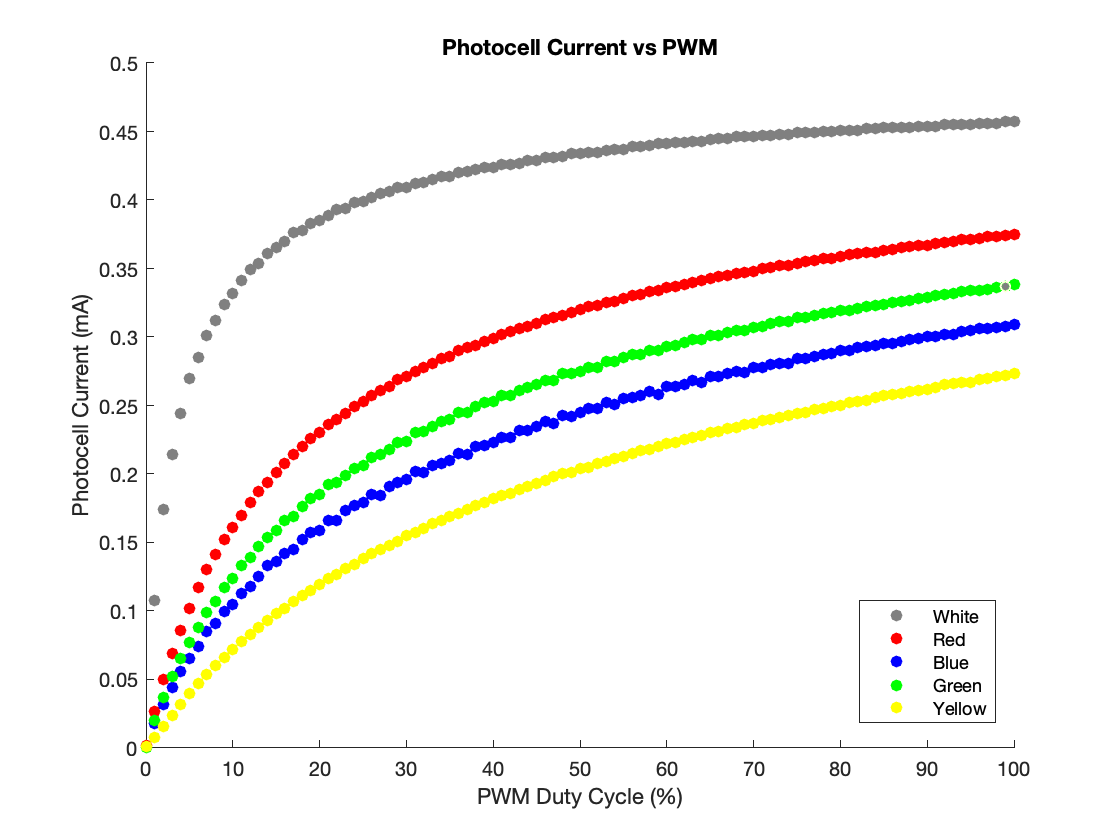

%Photocell Current vs Duty Cycle Plots
figure()
scatter(PWM, PhotocellCurrent_white*1000,[],[0.5 0.5 0.5],'filled')
title('Photocell Current vs PWM')
xlabel('PWM Duty Cycle (%)')
ylabel('Photocell Current (mA)')
hold on
scatter(PWM, PhotocellCurrent_red*1000, 'r', 'filled')
scatter(PWM, PhotocellCurrent_blue*1000, 'b', 'filled')
scatter(PWM, PhotocellCurrent_green*1000, 'g', 'filled')
scatter(PWM, PhotocellCurrent_yellow*1000, 'y', 'filled')
legend('White','Red','Blue','Green','Yellow', 'Location','best')
hold off

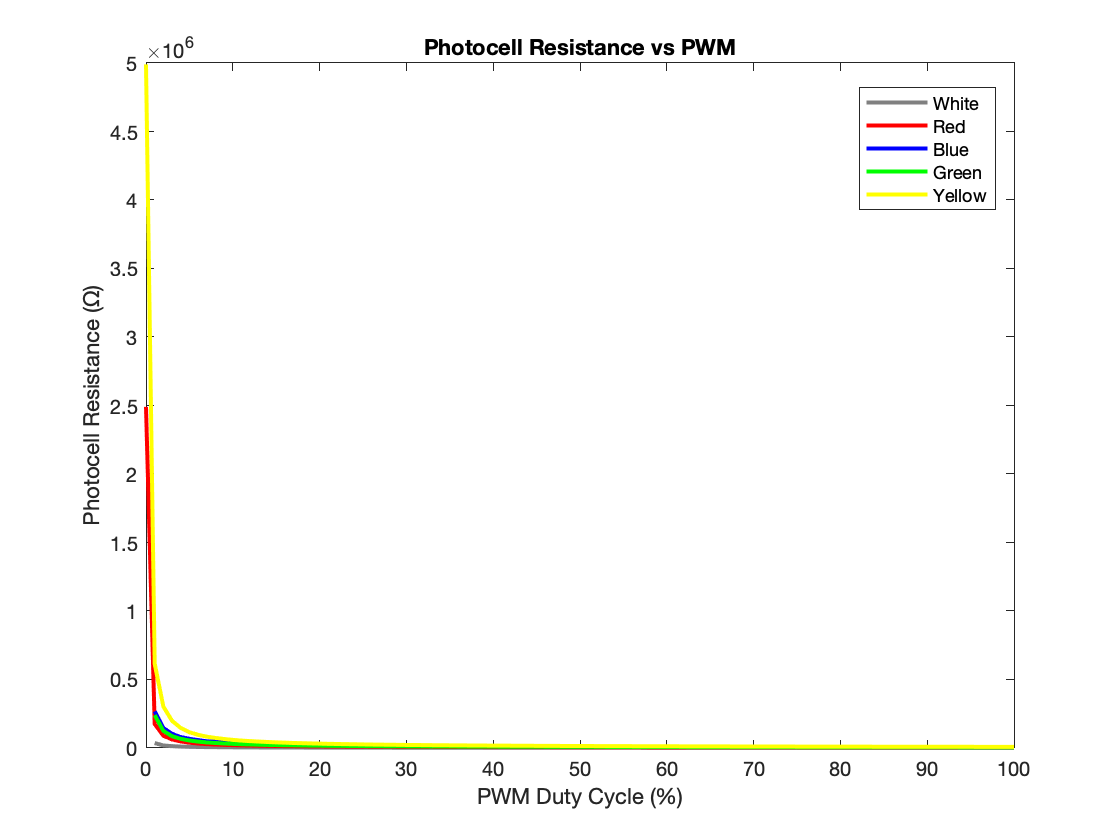


%Photocell Resistance vs Duty Cycle Plots 
plot(PWM, PhotocellResistance_white, 'color',[0.5 0.5 0.5],'LineWidth',2)
title('Photocell Resistance vs PWM')
xlabel('PWM Duty Cycle (%)')
ylabel('Photocell Resistance (Ω)')
hold on
plot(PWM, PhotocellResistance_red, 'r','LineWidth',2)
plot(PWM, PhotocellResistance_blue, 'b','LineWidth',2)
plot(PWM, PhotocellResistance_green, 'g','LineWidth',2)
plot(PWM, PhotocellResistance_yellow, 'y','LineWidth',2)
legend('White','Red','Blue','Green','Yellow', 'Location','best')
hold off

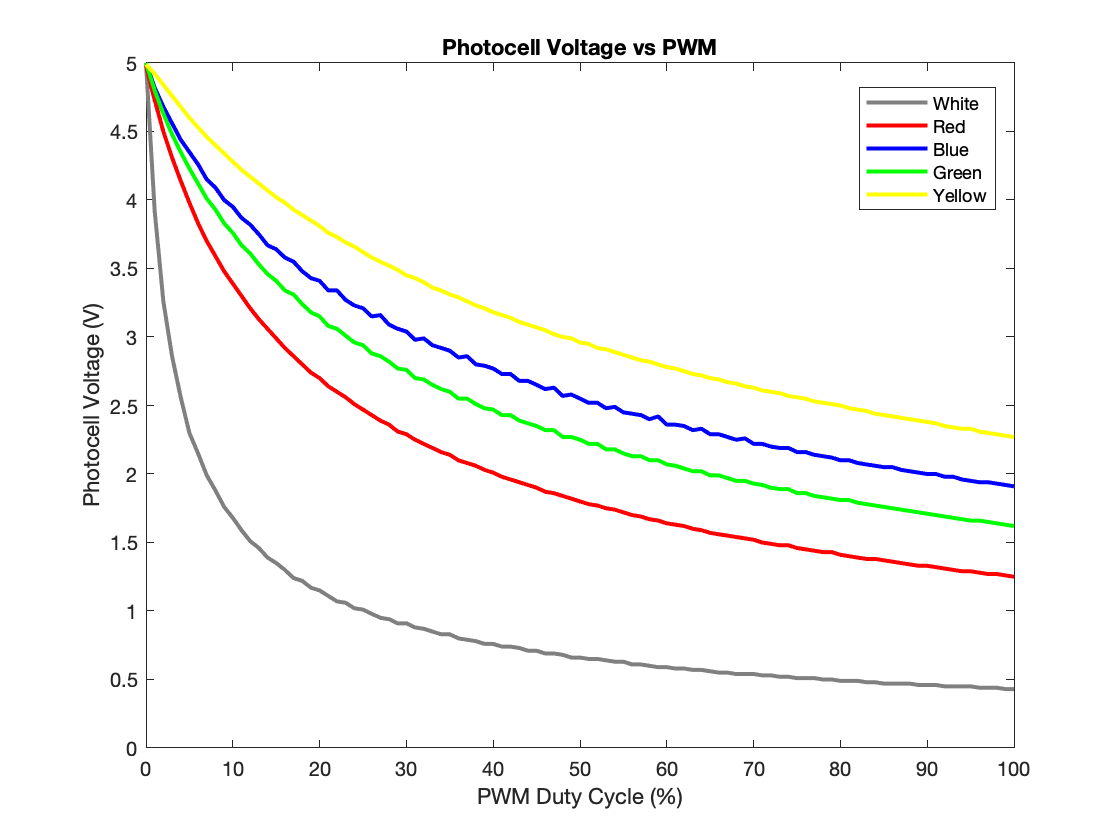


%Photocell Voltage vs Duty Cycle Plots 
plot(PWM, PhotocellVoltage_white, 'color',[0.5 0.5 0.5],'LineWidth',2)
title('Photocell Voltage vs PWM')
xlabel('PWM Duty Cycle (%)')
ylabel('Photocell Voltage (V)')
hold on
plot(PWM, PhotocellVoltage_red, 'r','LineWidth',2)
plot(PWM, PhotocellVoltage_blue, 'b','LineWidth',2)
plot(PWM, PhotocellVoltage_green, 'g','LineWidth',2)
plot(PWM, PhotocellVoltage_yellow, 'y','LineWidth',2)
legend('White','Red','Blue','Green','Yellow', 'Location','best')
hold off